#### EX 4-1 二维线图

clc;clear;figure;
x = 0:pi/15:2*pi;
y1 = sin(x);
y2 = sin(x-0.8);
y3 = sin(x-1.6);
% 将y1,y2,y3同时绘制在一个图中
% y2使用虚线，y3使用点线
p = plot(x,y1,x,y2,x,y3)

p =   3×1 Line 数组:

  Line
  Line
  Line

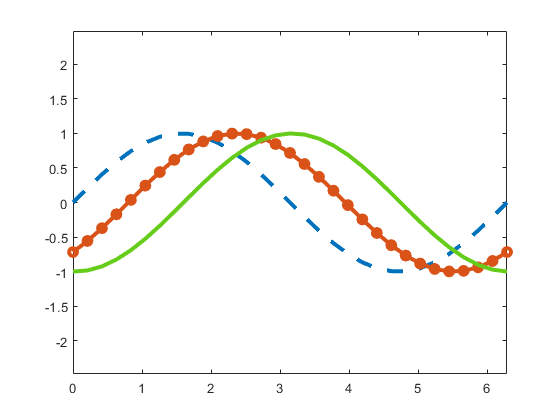

% 将线1的线型设为虚线
p(1).LineStyle = "--";
% 将线2的符号设为圆圈
p(2).Marker = 'o';
% 将线3的颜色设为绿色
p(3).Color = [0.4 0.8 0.1];
% 将所有线的线宽设为3
[p.LineWidth] = deal(3);
% 令XY两轴的数据单位相等
axis equal

#### EX 4-2 三维线图

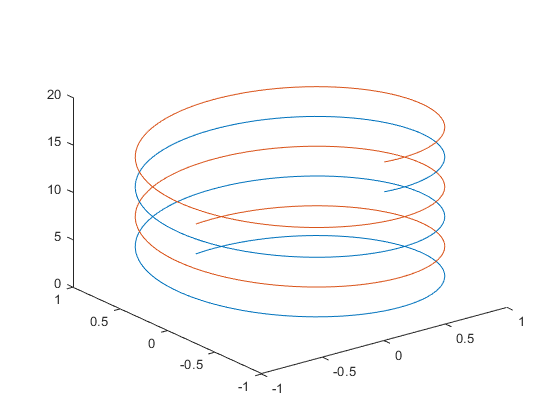

clc;clear;figure;
t = 0:pi/50:5*pi;
st = sin(t);
ct = cos(t);
plot3(st,ct,t);
hold on
plot3(st,ct,t+pi);
hold off

#### EX 4-3 误差线图

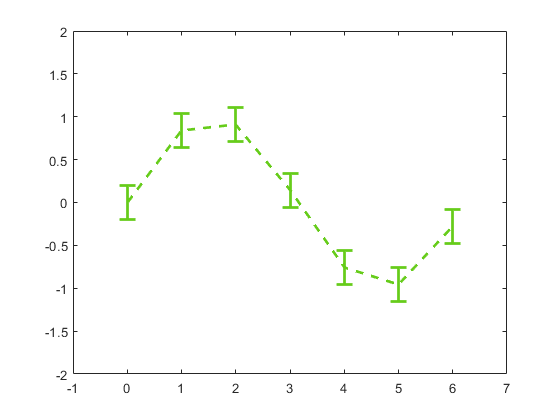

clc;clear;figure;
x = 0:6;
y = sin(x);
err = 0.2*ones(size(y));
e = errorbar(x,y,err);
% 属性赋值
e.LineWidth = 2;
e.Color = [0.4 0.8 0.1];
e.LineStyle = '--';
e.CapSize = 12;
xlim([-1 7.00]);
ylim([-2 2]);

#### EX 4-4 半对数图

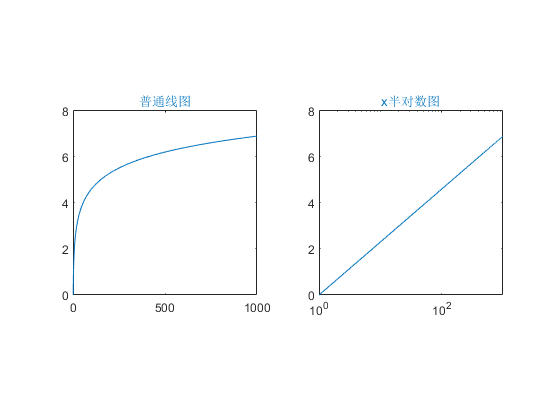

clc;clear;figure;
x = 0:1000; y = log(x);
% 建立左图
ax1 = subplot(1,2,1);
plot(ax1,x,y)
axis(ax1,'square')
t(1) = title(ax1,'普通线图'); % 左图标题
% 建立右图
ax2 = subplot(1,2,2);
semilogx(ax2,x,y)
axis(ax2,'square')
t(2) = title(ax2,'x半对数图'); % 右图标题
[t.Color] = deal([0.00,0.45,0.74]);

#### EX 4-5 显函数图

clc;clear;figure;

1.  普通表达式


$$y=\sin \left(x\right)$$


subplot(1,2,1)
y = @(x) sin(x)

y = 包含以下值的 function_handle :
    @(x)sin(x)

fplot(y)
axis square

2. 参数表达式


$$\left\lbrace \begin{array}{cc}
x=\cos \left(3t\right) & \;\\
y=\sin \left(2t\right) & \;
\end{array}\right.$$


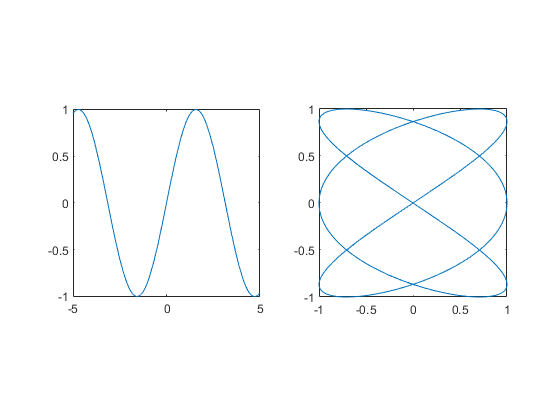

subplot(1,2,2)
xt = @(t) cos(3*t);
yt = @(t) sin(2*t);
fplot(xt,yt)
axis square

#### EX 4-6 隐函数图

隐函数：$y\;\sin \left(x\right)+x\;\sin \left(y\right)-1=0$

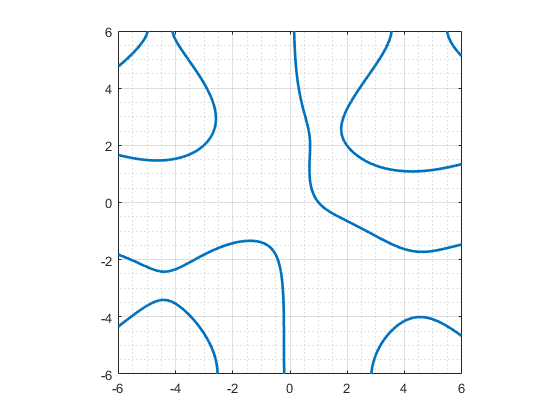

clc;clear;figure;
f = fimplicit(@(x,y) y.*sin(x)+x.*cos(y)-1);
axis equal
% 绘制网格线
grid on
% 绘制次网格线
grid minor
% x轴范围
f.XRange = [-6 6];
% y轴范围
f.YRange = [-6 6];
f.LineWidth = 2;

#### EX 4-7 饼图

clc;clear;figure;
a = [1, 3, 0.5, 2.5, 2];
% 准备标签名称
labels = {'A1','A2','B1','B2','C'};
% 准备隔离向量
e = zeros(size(a));
% 将色块4隔离
e(4)=1;
% 绘制饼图
p = pie(a,e)

p =   1×10 graphics 数组:

  列 1 至 8
    Patch    Text     Patch    Text     Patch    Text     Patch    Text 
  列 9 至 10
    Patch    Text 

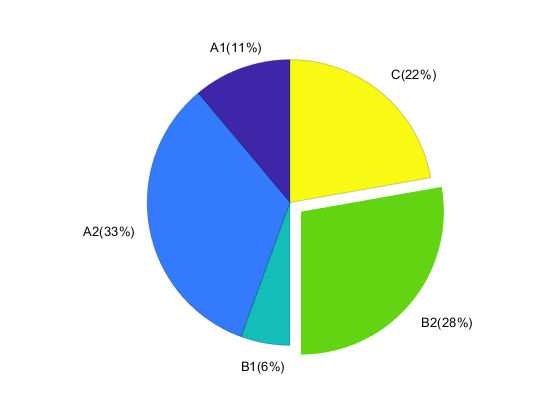

% 将标签名称后接入百分比
for i = 2:2:2*length(a)
    p(i).String = [labels{i/2}, '(',p(i).String,')'];
end
% 去除色块4的边线
p(7).EdgeColor = 'none';
% 修改色块4的颜色
p(7).FaceColor = [0.39,0.83,0.07];
% 修改所有色块的边线透明度
[p(1:2:9).EdgeAlpha] = deal(0.2);

#### EX 4-8 柱状图

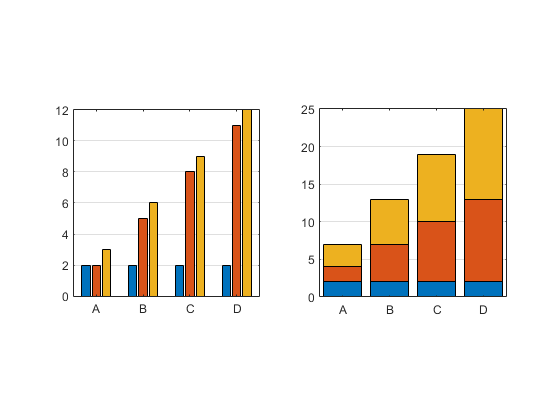

clc;clear;figure;
x = categorical({'A', 'B', 'C', 'D'});
y = [2 2 3; 2 5 6; 2 8 9; 2 11 12];
ax(1) = subplot(1,2,1); 
ax(2) = subplot(1,2,2);
bar(ax(1), x, y)
bar(ax(2), x, y, 'stacked')
% 所有坐标区均打开Y向网格
[ax.YGrid] = deal('on');
% 所有坐标区均为方形
axis(ax, 'square');

#### EX 4-9 直方图

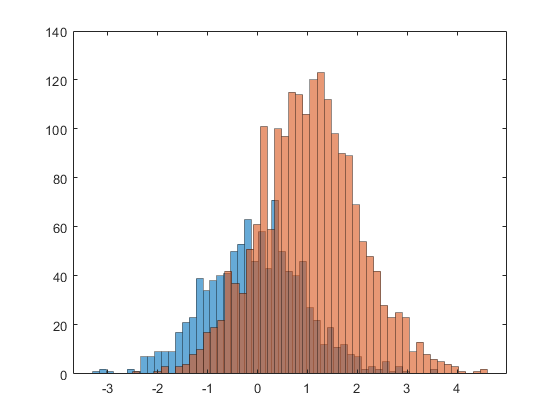

clc;clear;figure;
% 1000个随机变量
x = randn(1000,1);
% 2000个随机变量且加1
y = 1 + randn(2000,1);
% 设置条组（bin）的数量
nbins = 50;
h(1) = histogram(x,nbins);
hold on
h(2) = histogram(y,nbins);
hold off
% 设置所有条组的边线透明度
[h.EdgeAlpha] = deal(0.4);

#### EX 4-10 散点图

数据由参数方程定义：$\left\lbrace \begin{array}{cc}
x=e^{\theta } \;\sin \left(a\theta \right) & \;\\
y=e^{\theta } \;\cos \left(a\theta \right) & \;
\end{array}\right.$

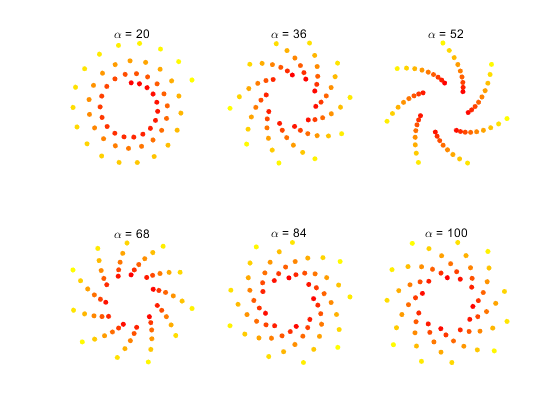

clc;clear;figure;
theta = linspace(0,1,60);
a = linspace(20,100,6);
for i=1:6
    ax(i) = subplot(2,3,i);
    x = exp(theta).*sin(a(i)*theta);
    y = exp(theta).*cos(a(i)*theta);
    % 颜色向量：线性均匀分布
    c=linspace(0,1,length(theta));
    % 设置颜色方案为："秋天"
    colormap autumn
    scatter(ax(i),x,y,15,c,'filled');
    axis off
    axis square
    % 对每个子图打印标题
    title(ax(i),['\alpha = ', num2str(a(i))]);
end

#### EX 4-11 直方散点图

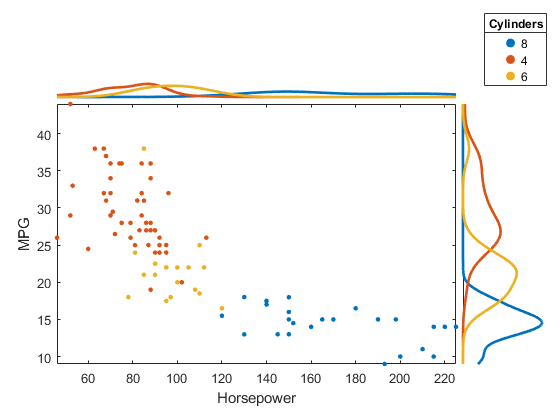

clc;clear;figure;
% 加载软件自带的汽车数据
load carsmall
% 建立表，包含马力/油耗/缸数
% MPG（miles per gallon）:每加仑行驶的英里数
t = table(Horsepower,MPG,Cylinders);
% 绘图，以马力和油耗作为横纵坐标
s = scatterhistogram(t,'Horsepower','MPG');
% 以缸数作为组分类依据值
s.GroupVariable = 'Cylinders';
% 将直方图显示类型设为光滑
s.HistogramDisplayStyle = "smooth";
% 设置合适的点尺寸
s.MarkerSize = 8;
s.LineWidth = 2;

#### EX 4-12 矩阵散点图

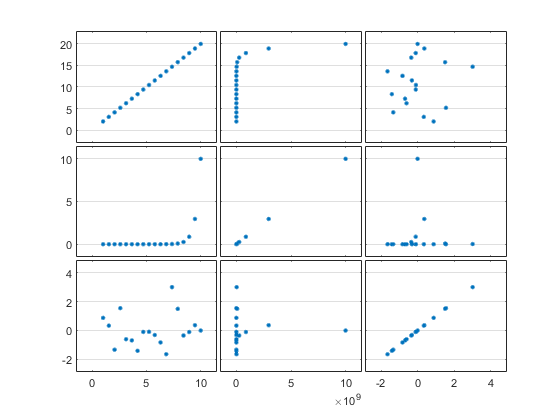

clc;clear;figure;
% 定义数据点个数
n = 18;
% 同时对x和y预分配
[x,y] = deal(zeros(n,3));
x(:,1) = linspace(1,10,n);
x(:,2) = logspace(1,10,n);
x(:,3) = randn(n,1);
y(:,1) = 2*linspace(1,10,n);
y(:,2) = 2+logspace(1,10,n);
y(:,3) = x(:,3);
% 矩阵散点图返回值
[S,AX,BigAx,H,HAx] = plotmatrix(x,y);
% 所有点的尺寸
[S.MarkerSize] = deal(9);
% 打开所有子图的Y向网格
[AX.YGrid] = deal('on');

#### EX 4-13 热图

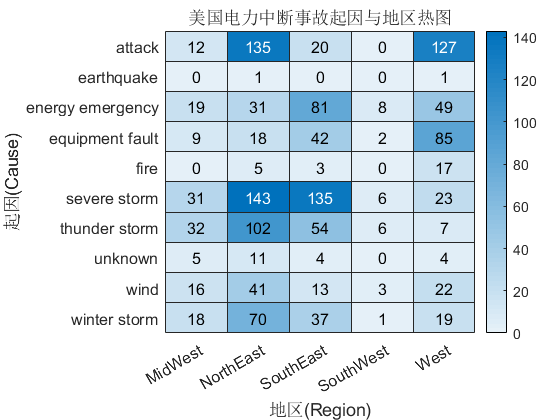

clc;clear;figure;
% 载入软件自带数据
% 将.csv文件直接读入table格式
T = readtable('outages.csv');
% 热图
h = heatmap(T,'Region','Cause');
% 标题
h.Title = '美国电力中断事故起因与地区热图';
% 横轴标签
h.XLabel = '地区(Region)';
% 纵轴标签
h.YLabel = '起因(Cause)';
% 字号
h.FontSize = 12;

#### EX 4-14 极坐标线图

clc;clear;figure;
theta = linspace(0,6*pi);
rho1 = theta/10;
p(1) = polarplot(theta,rho1);
rho2 = theta/13;
hold on
p(2) = polarplot(theta,rho2);
[p.LineWidth] = deal(2);
p(2).LineStyle = "--"

p =   1×2 Line 数组:

    Line    Line

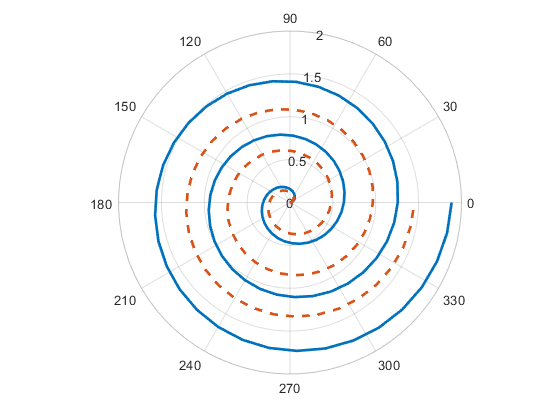

hold off

#### EX 4-15 极坐标直方图

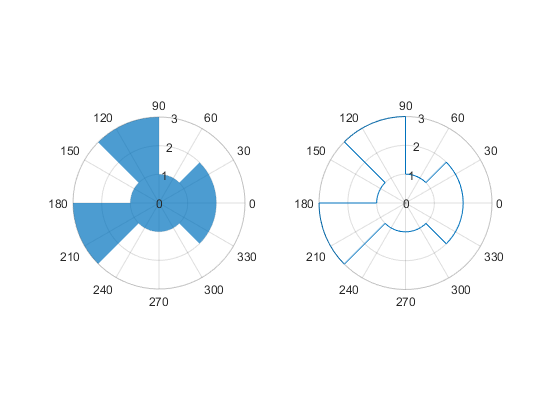

clc;clear;figure;
theta = [0.1 1.1 5.4 3.4 2.3 4.5 2.9 ...
    3.4 5.6 2.3 2.1 3.5 0.6 6.1];
ax(1) = subplot(1,2,1,polaraxes);
p(1) = polarhistogram(ax(1),theta,8);
p(1).LineStyle = 'none';
p(1).FaceAlpha = 0.7;
ax(2) = subplot(1,2,2,polaraxes);
p(2) = polarhistogram(ax(2),theta,8);
p(2).DisplayStyle = 'stairs';

#### EX 4-16 矩阵等高线图

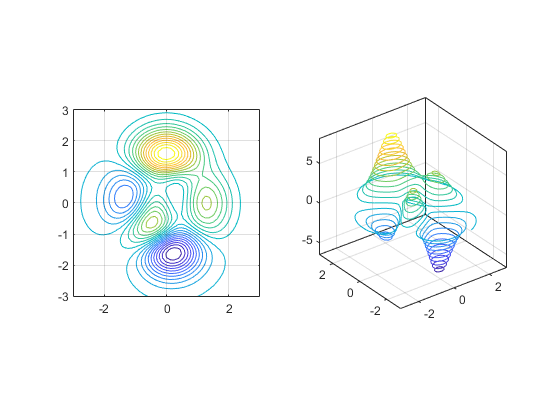

clc;clear;figure;
ax(1) = subplot(1,2,1);
ax(2) = subplot(1,2,2);
[X,Y,Z] = peaks;
% 返回M：等高线矩阵
% 返回c：等高线对象
[M1,c1] = contour(ax(1),X,Y,Z,24);
[M2,c2] = contour3(ax(2),X,Y,Z,24);
grid(ax(1),'on');
axis(ax,'square')

#### EX 4-17 `曲面图和网格图`

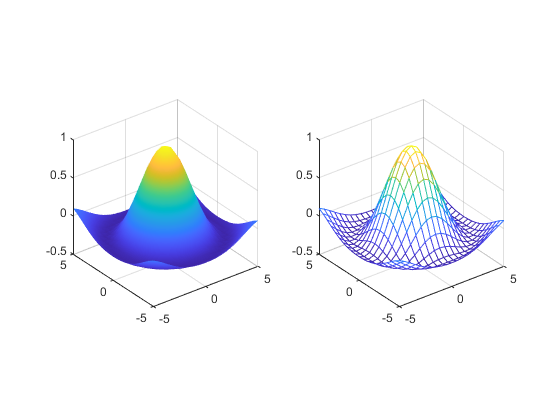

clc;clear;figure;
[X,Y] = meshgrid(-5:0.5:5);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
ax(1) = subplot(1,2,1);
ax(2) = subplot(1,2,2);
p(1) = surf(ax(1),X,Y,Z);
p(2) = mesh(ax(2),X,Y,Z);
axis(ax,'square');
shading(ax(1),'interp');
p(2).LineWidth = 0.2;

#### EX 4-18 向量图

绘制函数梯度方向分布：


$$z=xe^{-x^2 -y^2 }$$


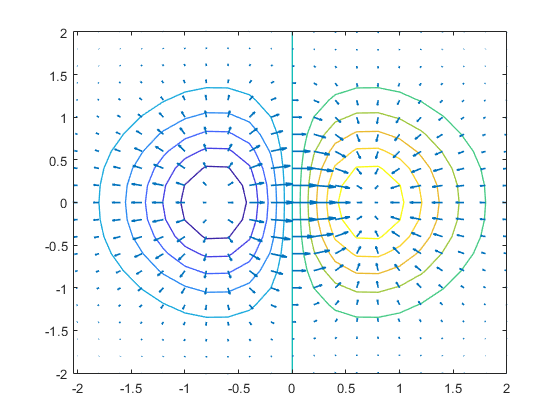

clc;clear;figure;
[X,Y] = meshgrid(-2:0.2:2);
Z = X.*exp(-X.^2 - Y.^2);
% 为Z的每个维度上的间距指定间距参数
[DX,DY] = gradient(Z,0.2,0.2);
[~,c] = contour(X,Y,Z,11);
c.LineWidth = 1;
hold on
q = quiver(X,Y,DX,DY);
q.LineWidth = 1.2;
q.MaxHeadSize = 0.5;
hold off

#### EX 4-19 三维体切片`图`

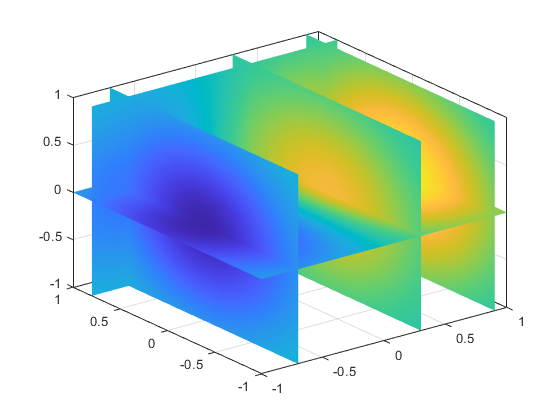

clc;clear;figure;
[X,Y,Z] = meshgrid(-1:0.1:1);
V = X.*exp(-X.^2-Y.^2-Z.^2);
% 设置要切平面的位置
xslice = [-0.7,0.3,0.9];   
yslice = [0.8];
zslice = 0;
s = slice(X,Y,Z,V,xslice,yslice,zslice);
% 去掉所有面上的线条
[s.LineStyle] = deal('none');
% 颜色插补
shading interp
box on

#### EX 4-20 锥体`图`

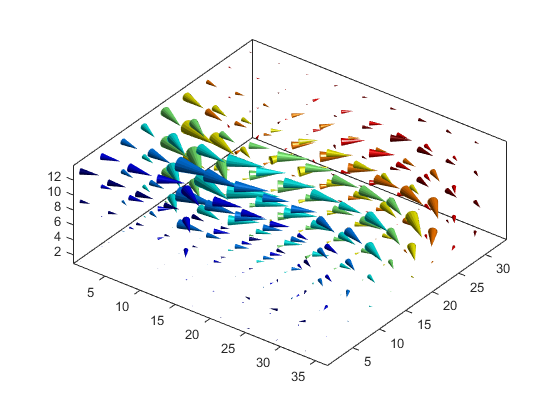

clc;clear;figure;
load wind u v w x y z                         
[m,n,p] = size(u);
[Cx, Cy, Cz] = meshgrid(1:4:m,1:4:n,1:4:p); 
h = coneplot(u,v,w,Cx,Cy,Cz,y,4); 
h.EdgeColor = "none";
% 坐标轴紧密围绕数据且相等单位
axis tight equal
% 指定视点
view(37,32)
% 显示坐标区轮廓
box on
% 颜色图配色方案为jet
colormap jet
% 创建光源
light

#### EX 4-21 作`图中文本与符号信息举例`

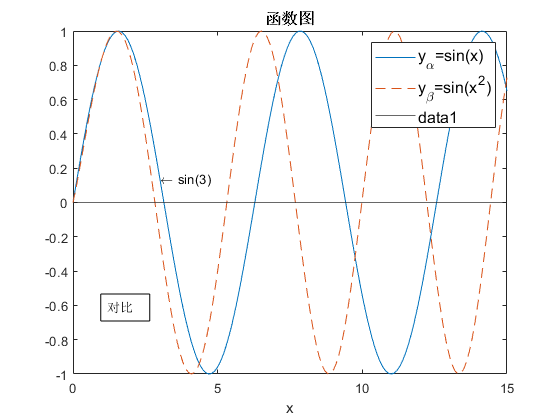

clc;clear;figure;
x = 0:0.1:15;
y_alpha = sin(x);
y_beta = sin(x.^1.1);
p = plot(x,y_alpha);
hold on;
plot(x,y_beta,'--');
hold off;
% 标题
t = title('函数图') ;
t.FontSize = 12;
t.FontWeight = "bold";
xlabel('x');
% 图例
l = legend(["y_{\alpha}=sin(x)","y_{\beta}=sin(x^2)"]);
l.FontSize = 12;
% 数据点文本说明
te = text(3,sin(3),'\leftarrow sin(3)');
% 常量水平线
yline(0);
% 注释
annotation('textbox',[.18 .2 .1 .1],'String','对比');

#### EX 4-22 坐标区外观举例

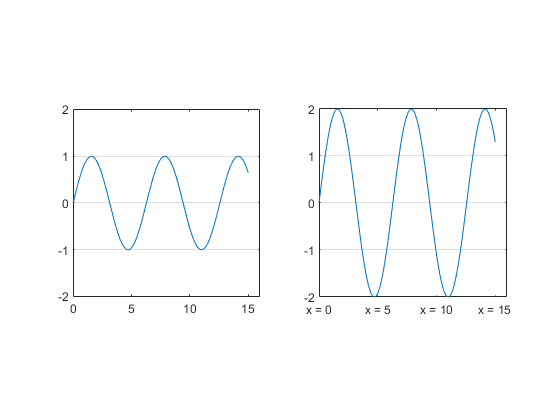

clc;clear;figure;
x = 0:0.1:15;
y = sin(x);
ax(1) = subplot(1,2,1); plot(x,y);
ax(2) = subplot(1,2,2); plot(x,2*y);
% 坐标轴取为正方形
axis(ax, "square");
% X坐标轴范围（属性赋值法）
[ax.XLim] = deal([0 16]);
% Y坐标轴范围（函数赋值法）
ylim(ax(1), [-2 2]);
% 打开Y向网格线
[ax.YGrid] = deal("on");
% 设置X刻度
xticks([0 5 10 15]);
% 对于每个刻度处设置标签
xticklabels({'x = 0','x = 5','x = 10','x = 15'});

#### EX 4-23 颜色栏与配色方案

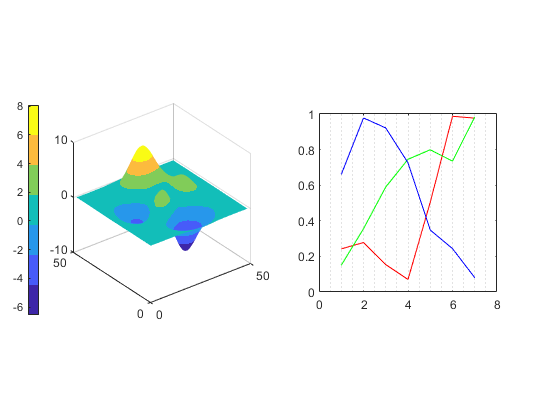

clc;clear;figure;
ax(1) = subplot(1,2,1);
surf(peaks); shading interp;
cb = colorbar; % 绘制颜色栏
cb.Position = [0.05,0.25,0.02,0.5];
colormap parula(7); % 选择配色方案
ax(2) = subplot(1,2,2);
rgbplot(parula(7)); % 分析配色方案RGB强度
axis(ax, "square");
ax(2).XMinorGrid = "on"; % 打开副网格

#### EX 4-24 三维渲染

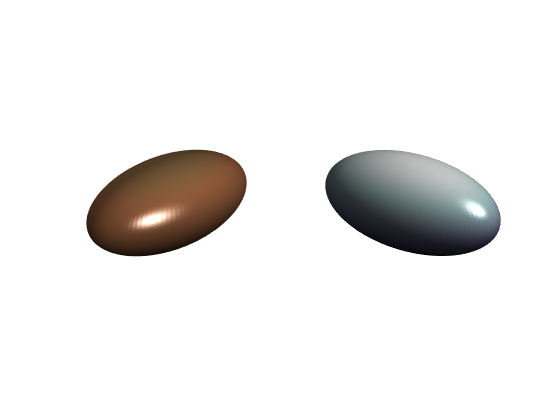

clc;clear;figure;
[x,y,z] = ellipsoid(0,0,0,8,4,4,100);
ax(1) = subplot(1,2,1);     ax(2) = subplot(1,2,2);
s(1) = surf(ax(1),x,y,z);   s(2) = surf(ax(2),x,y,z);
view(ax(2),[30,30]); % 修改视角方向
axis(ax, 'vis3d'); % 旋转时纵横比不变
colormap(ax(1),'copper'); % “铜”配色
colormap(ax(2),'bone'); % "骨”配色
shading(ax(1), 'interp'); % 插值着色
shading(ax(2), 'flat'); % 单片一致着色
l(1) = light(ax(1)); l(2) = light(ax(2)); % 打开光照
l(1).Position = [0 -10 1.5]; % 调整光照位置
lighting(ax(2),"flat"); % 均匀分布光照
material(s(1),"metal"); % 金属质感
material(s(2),"shiny"); % 光亮质感
axis(ax, "equal"); axis(ax,"off");

#### EX 4-25 实用技巧

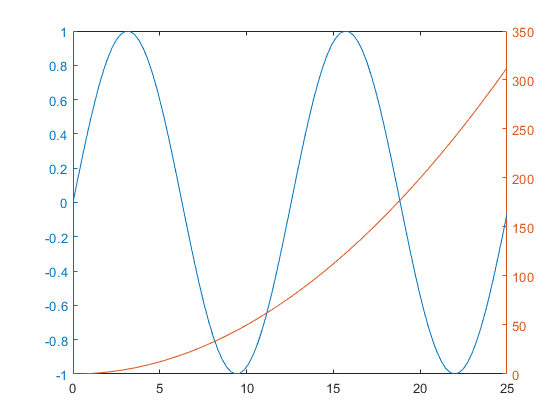

clc;clear;figure;
x = linspace(0,25);
y = sin(x/2);
yyaxis left
p1 = plot(x,y);
r = x.^2/2;
yyaxis right
p2 = plot(x,r);

#### EX 4-26 图像读写处理

clc;clear;figure;
% 将图片读入矩阵I
I = imread('peppers.png');
classIm = class(I)

classIm = 'uint8'

sizeIm = size(I)

sizeIm =    384   512     3


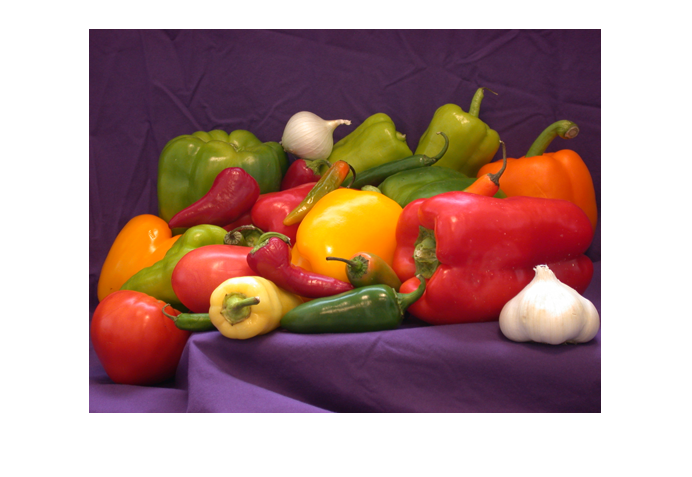

% 显示矩阵I
imshow(I);

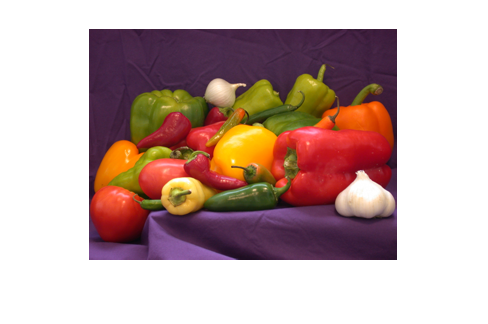

% 将矩阵I压缩为原来尺寸的60%
J = imresize(I, 0.6);
imshow(J)

% 保存矩阵J
imwrite(J,'peppersResize.png');

#### EX 4-27 图像算术运算

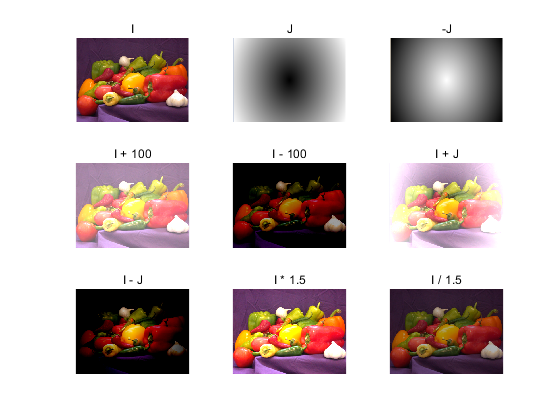

clc;clear;figure;
I = imread('peppersOrigin.png');
J = imread('gradientRamp.png');
% 第一行
subplot(3,3,1); imshow(I); title('I');
subplot(3,3,2); imshow(J); title('J');
subplot(3,3,3); imshow(imcomplement(J)); title('-J');
% 第二行
subplot(3,3,4); imshow(imadd(I,100)); title('I + 100');
subplot(3,3,5); imshow(imsubtract(I,100)); title('I - 100');
subplot(3,3,6); imshow(imadd(I,J)); title('I + J');
% 第三行
subplot(3,3,7); imshow(imsubtract(I,J)); title('I - J');
subplot(3,3,8); imshow(immultiply(I,1.5)); title('I * 1.5');
subplot(3,3,9); imshow(imdivide(I,1.5)); title('I / 1.5');

#### EX 4-28 图像逻辑运算

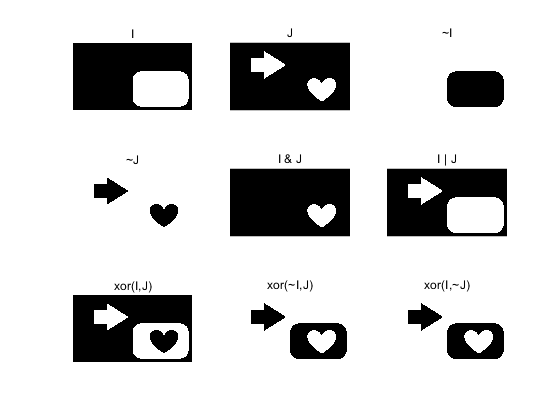

clc;clear;figure;
I = im2bw(imread('logical1.bmp'));
J = im2bw(imread('logical2.bmp'));
% 第一行
subplot(3,3,1); imshow(I); title('I');
subplot(3,3,2); imshow(J); title('J');
subplot(3,3,3); imshow(~I); title('~I');
% 第二行
subplot(3,3,4); imshow(~J); title('~J');
subplot(3,3,5); imshow(I&J); title('I & J');
subplot(3,3,6); imshow(I|J); title('I | J');
% 第三行
subplot(3,3,7); imshow(xor(I,J)); title('xor(I,J)');
subplot(3,3,8); imshow(xor(~I,J)); title('xor(~I,J)');
subplot(3,3,9); imshow(xor(I,~J)); title('xor(I,~J)');

#### EX 4-29 图像几何运算

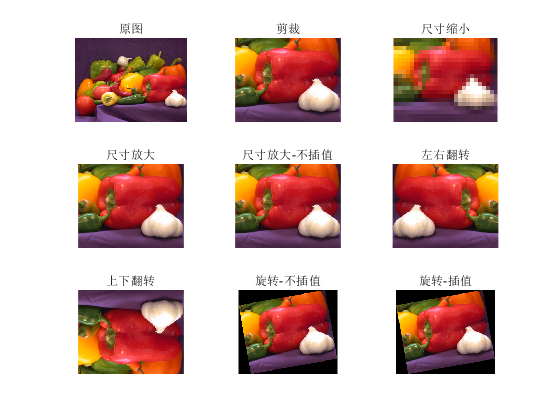

clc;clear;figure;
I = imread('peppersOrigin.png');
% 第一行
subplot(3,3,1);imshow(I); title('原图');
J = imcrop(I, [260 140 300 200]);
subplot(3,3,2);imshow(J); title('剪裁');
subplot(3,3,3);
imshow(imresize(J, 0.1)); title('尺寸缩小');
% 第二行
subplot(3,3,4);
imshow(imresize(J, 10)); title('尺寸放大'); % 默认双三次插值
subplot(3,3,5);
imshow(imresize(J, 10, "nearest")); title('尺寸放大-不插值');
subplot(3,3,6);
imshow(fliplr(J)); title('左右翻转');
% 第三行
subplot(3,3,7);imshow(flipud(J)); title('上下翻转');
subplot(3,3,8);imshow(imrotate(J,10)); title('旋转-不插值');
subplot(3,3,9);
imshow(imrotate(J,10,"bicubic")); title('旋转-插值');

#### EX 4-30 图像灰度运算

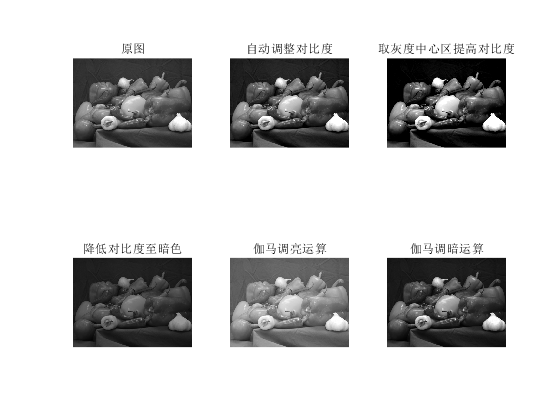

clc;clear;figure;
I = rgb2gray(imread('peppersOrigin.png'));
% 第一行
subplot(2,3,1);imshow(I); title('原图');
subplot(2,3,2);imshow(imadjust(I)); title('自动调整对比度');
subplot(2,3,3);
imshow(imadjust(I,[0.2 0.8],[0 1])); title('取灰度中心区提高对比度');
% 第一行
subplot(2,3,4);
imshow(imadjust(I,[0 1],[0 0.6])); title('降低对比度至暗色');
subplot(2,3,5);
imshow(imadjust(I,[],[],0.6)); title('伽马调亮运算');
subplot(2,3,6);
imshow(imadjust(I,[],[],1.4)); title('伽马调暗运算');

#### EX 4-31 动画实例1

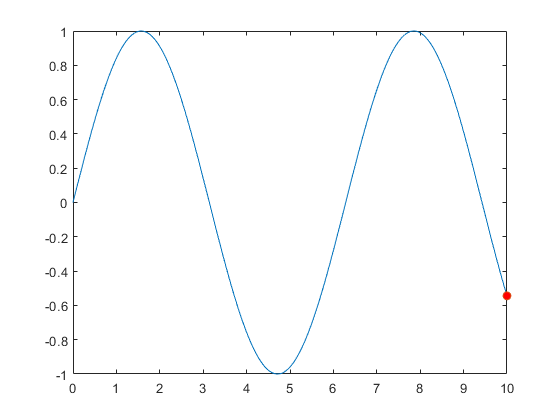

clc;clear;figure;
% 选中以下代码 按F9键执行
figure
x = linspace(0,10,1000);
y = sin(x);
plot(x,y)
hold on
p = plot(x(1),y(1),'o','MarkerFaceColor','red');
hold off
axis manual
for k = 2:2:length(x)
    p.XData = x(k);
    p.YData = y(k);
    drawnow
end

#### EX 4-32 动画实例2-保存视频

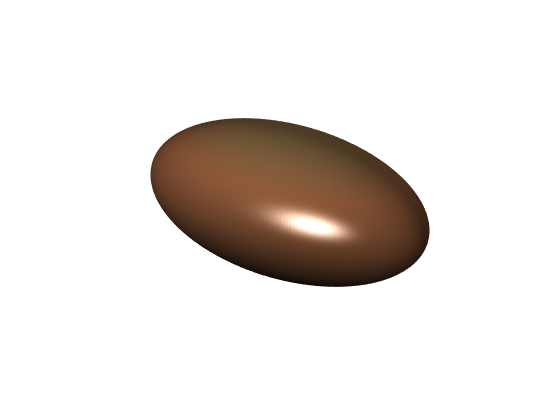

clc;clear;figure;
% 选中以下代码 按F9键执行
[x,y,z] = ellipsoid(0,0,0,8,4,4,250);
figure; % 新建图窗
ax = gca; % 取当前坐标区
s = surf(x,y,z);  
axis vis3d; % 旋转时纵横比不变
colormap copper; % “铜”配色
shading interp; % 插值着色
l = light(ax);  % 打开光照
l.Position = [0 -10 1.5]; % 调整光照位置
material metal; % 金属质感
axis equal; axis off;
% 创建视频文件并打开
v = VideoWriter('videoRot.avi'); open(v)
for k = 30:2:390
   ax.View = [k 30]; 
   drawnow
   m = getframe(gcf); writeVideo(v,m);
end

close(v) % 关闭视频文件